# EXERCISE #2 : Use the Simplest WLAN Network to Study QoS and Interference

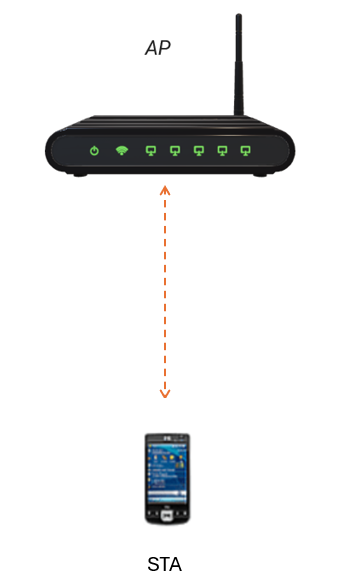

WLAN Network with one AP and one STA 

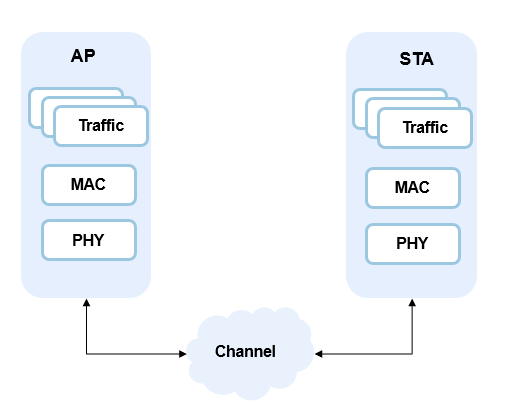

Modeled Blocks 

#### In this exercise, You will learn how to  

- Configure and create WLAN nodes and networks

- Simulate the WLAN network and capture statistics

- Visualize the WLAN MAC state machine

- Analyze WLAN network performance under Bluetooth interference

Copyright 2024-2025 The MathWorks, Inc

#### Cleanup

clear;
format default;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 

### General settings

- `2.4 GHz band`

- `20 MHz wide channel`

- `Channel 7`

- [https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html](https://www.mathworks.com/help/releases/R2024b/wlan/gs/wlan-radio-frequency-channels.html)

band        = 2.4;
bandwidth   = 20e6;
channel     = 7;
fc          = wlanChannelFrequency(channel,band);
txPower     = 0.0; % dBm - Use 0 dBm to make calculations easy. The received power is equal to negative of path loss. 
txGain      = 0.0; % dB  - Will use this field to mimic additional attenuation

- `Time Unit = 1024us`

TU              = 1024e-6; % Time Unit(TU) in WLAN is 1024 us 
simulationTime  = 100*TU;  % Simulation time is set to 100*TU 

### Geometry

- Define position of AP and STA

% Adjust relative positions of AP and STA to change SNR
% range -15m, +15m in X and Y (limited by plotStations utility function, but could be updated if needed)
AP_pos  = [0,0,0];
STA_pos = [5,5,0];
% Utility function to plot AP, STA, distance and fspl
[dist, atten] = plotNodesPositions(AP_pos,STA_pos,fc);

#### Create a wirelessNetworkSimulator instance

networkSimulator = wirelessNetworkSimulator.init;

#### Select Interference Modeling Options

interferenceModeling = "overlapping-adjacent-channel";  
maxInterferenceOffset = 0;

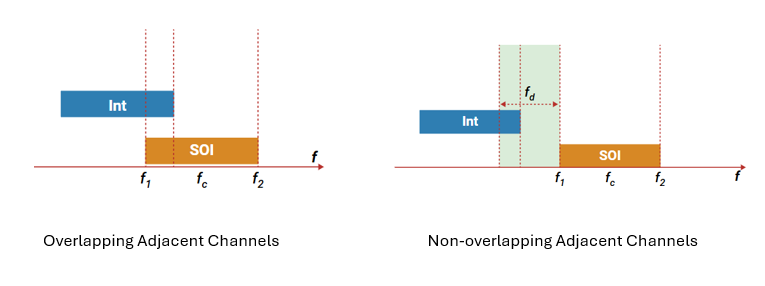

#### Enable or Disable Aggregation 

enableAggregation = true;

#### QoS Parameters

% Define EDCA (Enhanced Distributed Channel Access) parameters 
% for the four Access Categories (ACs): [Best Effort, Background, Video, Voice]
% Arbitrary Interframe Space (AIFS) values for each AC, in slot times (1 slot = 9 µs)
aifs = [4 7 3 2];
% Minimum Contention Window (CWmin) values for each AC, in slot counts
cwMin = [15 15 7 3];
% Maximum Contention Window (CWmax) values for each AC, in slot counts
cwMax = [1023 1023 15 7];
% Transmission Opportunity (TXOP) duration limits for each AC,
% in units of 32 microseconds
txopLimit = [1 2 4 8];

#### Create the AP

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat", "HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",txPower, ...    
    "TransmitGain",txGain, ...
    "MCS",6, ...
    "AggregateHTMPDU",enableAggregation, ...
    "BeaconInterval", 10, ...
    "InitialBeaconOffset",1, ...
    "InterferenceModeling",interferenceModeling, ...
    "MaxInterferenceOffset",maxInterferenceOffset, ...
    "CWMax",cwMax, ...
    "CWMin",cwMin, ...
    "AIFS",aifs, ...
    "TXOPLimit",txopLimit);
     

macabstraction = false;
phyabstraction = "none";

Note: All nodes on the network must have same MAC and PHY abstractions  

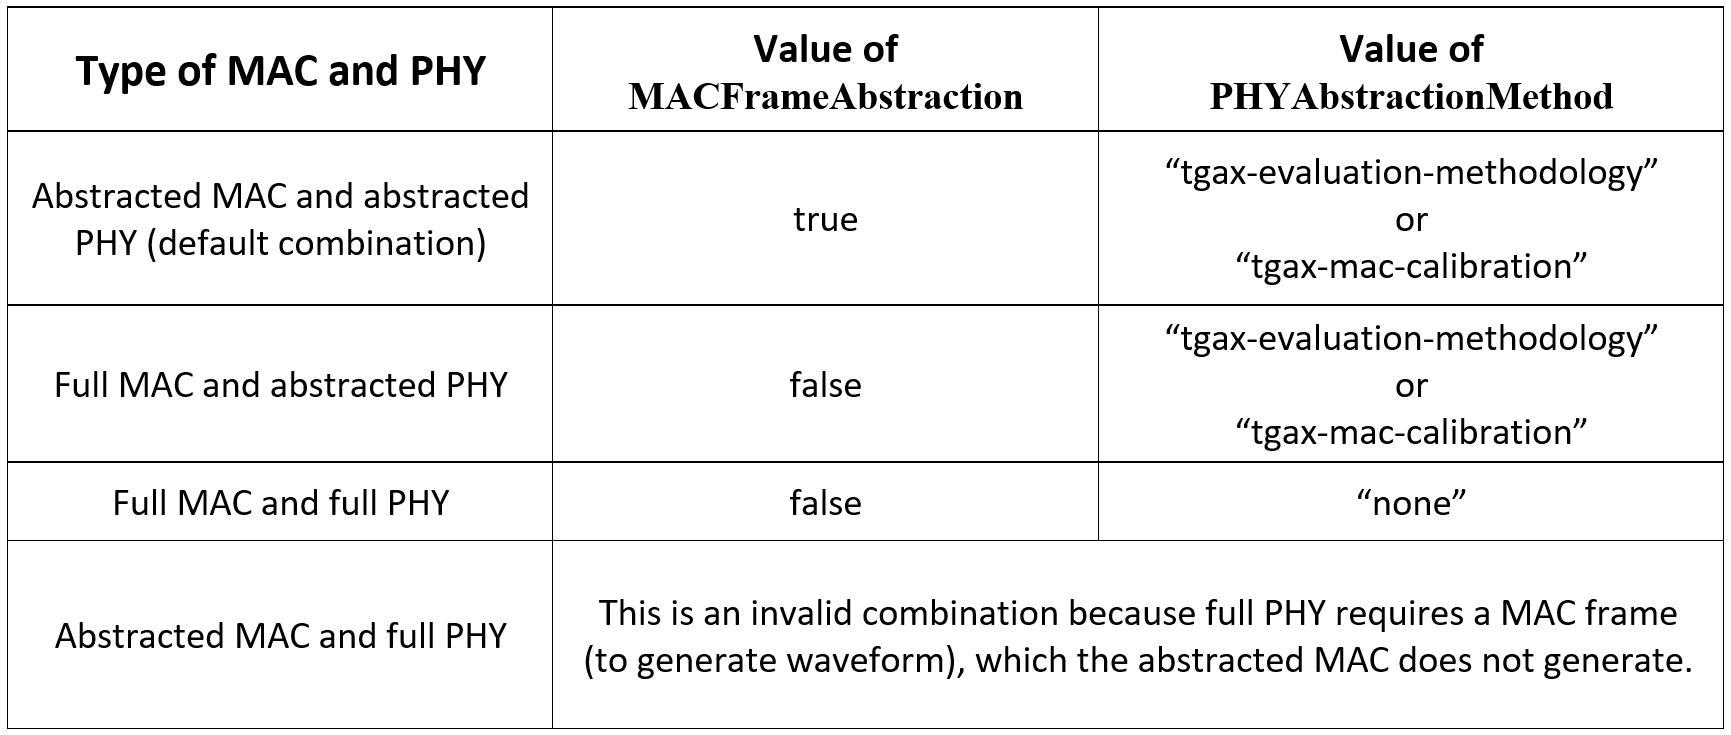

AP = wlanNode(...
    "Name","AP",...
    "Position",AP_pos, ...
    "DeviceConfig",APCfg,...    
    "MACFrameAbstraction",macabstraction,...
    "PHYAbstractionMethod",phyabstraction); 

### Create the STA

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ... 
    "AggregateHTMPDU",enableAggregation, ...
    "MCS",6, ...
    "InterferenceModeling",interferenceModeling, ...
    "MaxInterferenceOffset",maxInterferenceOffset);

STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
    "MACFrameAbstraction",macabstraction,...
    "PHYAbstractionMethod",phyabstraction);

#### Create the network 

associateStations(AP,STA,"FullBufferTraffic","off");

dataRate = 10000; %kpbs

# Task #1/4 Configure a traffic model 

% Define traffic type

% Use networkTrafficOnOff() function to configure QoS Traffic
% Write configuration in a variable named "trafficCfg"
% Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% onTime = Inf
% OffTime = 0
% DataRate = dataRate kpbs
% PacketSize = 512

% <enter code below>
% trafficCfg =

% Plot traffic pattern
plotTrafficPattern(simulationTime,trafficCfg);


# Task #2/4 Integrate a traffic model into AP with "AccessCategory",2

#### Specify a priority level 0 for the generated traffic 

accessCategory_1 = 2;
% Add traffic from source to destination
% Use addTrafficSource() function to add the traffic to simulation
% Source is "AP",traffic configuration is "trafficCfg", Destination is "STA"
% First argument is AP
% Second argument is trafficCfg
% Third argument is "DestinationNode",STA
% Fourth argument is "AccessCategory",accessCategory_1
% Hint: Click the link below and see the "Syntax" section.

### [Help on adding traffic source to a node ](https://www.mathworks.com/help/wlan/ref/wlannode.addtrafficsource.html)

% <enter code below>


# Task #3/4 Configure another traffic model 

% Define traffic type

% Use networkTrafficOnOff() function to configure QoS Traffic
% Write configuration in a variable named "trafficCfg"
% Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% onTime = inf
% OffTime = 0
% DataRate = dataRate kpbs
% PacketSize = 513


% <enter code below>
% trafficCfg =

# Task #4/4 Integrate a traffic model into AP with "AccessCategory",3

accessCategory_2 = 3;
% Add traffic from source to destination
% Use addTrafficSource() function to add the traffic to simulation
% First argument is AP
% Second argument is trafficCfg
% Third argument is "DestinationNode",STA
% Fourth argument is "AccessCategory",accessCategory_2
% Hint: Click the link below and see the "Syntax" section.

### [Help on adding traffic source to a node ](https://www.mathworks.com/help/wlan/ref/wlannode.addtrafficsource.html)

% <enter code below>



#### Introduce **Bluetooth interference** into the simulation to study coexistence effects

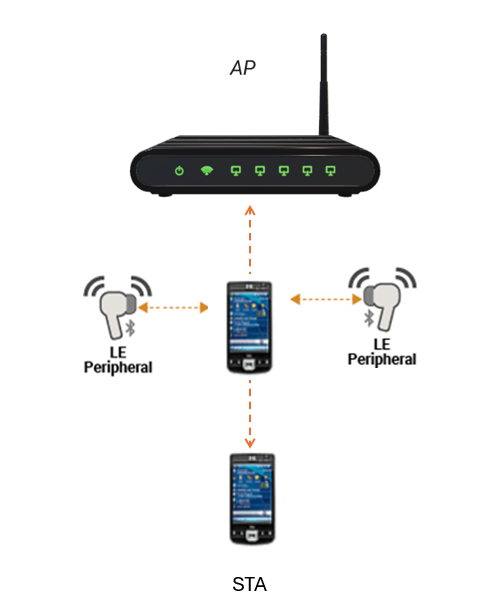

enableBluetoothLEInterference = false;
if enableBluetoothLEInterference
    % Create a Bluetooth LE Central node as an interferer
    source = bluetoothLENode("central","Name","Interferer-1",Position=[1,0,0],TransmitterPower=20, TransmitterGain=0,ReceiverGain=0,ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling,MaxInterferenceOffset=maxInterferenceOffset);
    % Create a Bluetooth LE Peripheral node as an interferer
    leftSink = bluetoothLENode("Peripheral", Position=[3.2,3,0],Name="interferer-2",TransmitterPower=0, TransmitterGain=0, ReceiverGain=0,ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling,MaxInterferenceOffset=maxInterferenceOffset);
    % Create another Bluetooth LE Peripheral node as an interferer
    rightSink = bluetoothLENode("Peripheral", Position=[3,3,0],Name="interferer-3",TransmitterPower=0,TransmitterGain=0,ReceiverGain=0, ReceiverSensitivity=-100,InterferenceModeling=interferenceModeling);
    % Configure Bluetooth LE multicast audio
    cfgCIS = bluetoothLECISConfig(ISOInterval=0.050,NumSubevents=9,BurstNumber=9,SubInterval= 2.5e-3,MaxPDU= 251,FlushTimeout= 1,TMSS= 150e-6,TIFS= 150e-6);
    % Configure a Bluetooth LE connection for control packets
    cfgConnection = bluetoothLEConnectionConfig(ConnectionInterval=0.1,ActivePeriod=0.001,MaxPDU=27,PHYMode="LE2M");
    % Configure a Bluetooth LE connection for control packets
    cfgConnection.AccessAddress = "5DA44270"; cfgConnection.ConnectionOffset = 0; [leftConnCfg,leftCISCfg] = configureConnection(cfgConnection,source,leftSink,CISConfig=cfgCIS);
    cfgConnection.AccessAddress = "5DA44271"; cfgConnection.ConnectionOffset = 0.05; [rightConnCfg,rightCISCfg] = configureConnection(cfgConnection,source,rightSink,CISConfig=cfgCIS);
    % Add Bluetooth audio traffic
    leftSinkTraffic = networkTrafficOnOff(DataRate=320,PacketSize=cfgCIS.MaxPDU,GeneratePacket=true,OnTime=Inf,OffTime=0);
    rightSinkTraffic = networkTrafficOnOff(DataRate=320,PacketSize=cfgCIS.MaxPDU,GeneratePacket=true,OnTime=Inf,OffTime=0);
    addTrafficSource(source,leftSinkTraffic,DestinationNode=leftSink,CISConfig=leftCISCfg);
    addTrafficSource(source,rightSinkTraffic,DestinationNode=rightSink,CISConfig=rightCISCfg);
    intBluetoothLENodes = [source leftSink rightSink];
end

#### **Add nodes to the network **

wlanNodes = [AP, STA];
addNodes(networkSimulator,wlanNodes)

**Add Bluetooth nodes to the network **

if enableBluetoothLEInterference 
    addNodes(networkSimulator,intBluetoothLENodes);
end
nodes = networkSimulator.Nodes;

#### Add channel model to the simulator

channelModel = "TGAX";
if strcmp(channelModel,"TGAX")
    channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
    addChannelModel(networkSimulator,channel.ChannelFcn);
end

**Enable PCAP capture**

enablePCAPCapture = true;
if enablePCAPCapture
    capturePacketsObj = hExportWLANPackets(wlanNodes, 'pcap', true);
end

#### Enable packet visualization

enablePacketVisualization = true; 
if enablePacketVisualization
     enableFrequencyVisualization = false;  
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=enableFrequencyVisualization);
end

#### Run the simulation

- WirelessNetworkSimulator is an event-driven simulator

- use the run() method to start the simulation

% Create node performance visualization object
perfViewerObj = hPerformanceViewer(wlanNodes,simulationTime);
run (networkSimulator,simulationTime)

#### Print QoS Statistics 

APStatistics  = statistics(AP,"all");
STAStatistics = statistics(STA);
[BestEffort, Background, Video,Voice ] = APStatistics.MAC.AccessCategories.TransmittedDataFrames;
fprintf(['Best Effort: %d Packets\n ' ...
         'Background: %d Packets\n ' ...
         'Video: %d Packets\n ' ...
         'Voice: %d Packets'], ...
          BestEffort, ...
          Background, ...
          Video, ...
          Voice);

#### Calculate throughput, packet loss ratio,latency at nodes 

% Calculate throughput (Mbps) at Nodes
throughputs = throughput(perfViewerObj,[wlanNodes(:).ID])
% Calculate packet loss ratio at Nodes
packetLossRatio = packetLossRatio(perfViewerObj,[wlanNodes(:).ID])
% Calculate Latency (Seconds) at Nodes
averageReceiveLatency = averageReceiveLatency(perfViewerObj,[wlanNodes(:).ID])
if enablePCAPCapture
    delete(capturePacketsObj.PCAPObjList);
end